## Data Input


close all;
clear all;
colors=npg(10); % Ten basic colors 
maindir='\\Artemis-pc\e\Data\2023-12-28\Abs-366\';
main_dir_0=maindir;
load([maindir,'\population.mat']);
%load([maindir,'\allan.mat']);



delete_odd = 1;   % 删除异常组或长漂
delete_num = 20;

tau_single = 22.51;   % 单组时序时长
T = 5.1;   % Interrogation time

omega = 2*pi/75.9e-3;
amp = 0.9395;

phase = (s1-s2)./(s1+s2);
atom_num = n1+n2;

if delete_odd == 1
    phase(1:delete_num) = [];
    atom_num(1:delete_num) = [];
end

delta_omega = phase./T./amp;

atom_n = mean(atom_num);
shot_noise = 1/sqrt(atom_n);

projective = shot_noise/amp;


## Allan Deviation

### Freq Allan

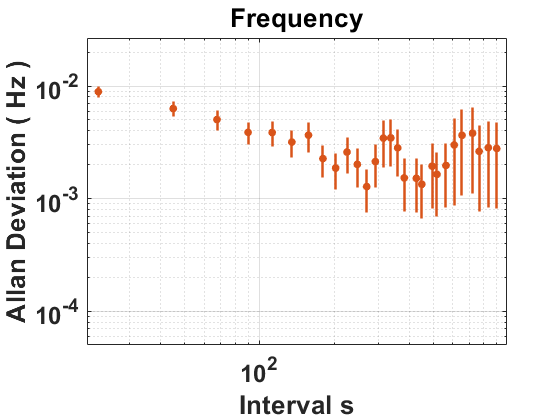


y_lim_low1 = 5e-5;

[tau_k,allan_freq,freq_std] = allan_deviation(delta_omega./(2*pi));

tau = tau_single.*tau_k;
freq_shot = shot_noise./(2*pi*sqrt(tau_k).*T);
freq_projective = freq_shot/amp;

h1 = figure;
I1 = errorbar(tau,allan_freq,freq_std,'.','Color',[0.85 0.33 0.1],...
    'MarkerSize',20,'CapSize',0,'LineWidth',1.8);

%plot(tau,allan_freq,'.','Color',[0.85 0.33 0.1],'MarkerSize',20);

xlim([min(tau)*0.9 max(tau)*1.1]);
ylim([y_lim_low1 max(allan_freq)*3]);

xlabel('Interval s');
ylabel('Allan Deviation ( Hz )');
title('Frequency','FontName','Arial','FontWeight','bold');

grid on;
set(gca,'FontSize',18,'FontName','Arial','FontWeight','bold',...
    'XScale','log','YScale','log');
set(gcf,'Visible','on');

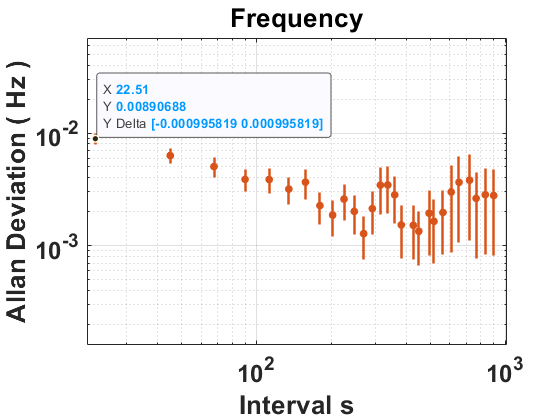


if delete_odd == 0
    savefig(h1,[main_dir_0,'freq_allan_all.fig']);
    saveas(h1,[main_dir_0,'freq_allan_all.png']);
elseif delete_odd == 1
    savefig(h1,[main_dir_0,'freq_allan.fig']);
    saveas(h1,[main_dir_0,'freq_allan.png']);
end

### Shot Noise Limit and Projective Limit

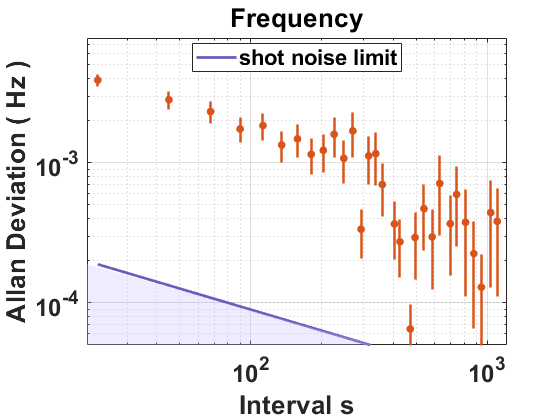


hold on;

l1 = plot(tau,freq_shot,'-','LineWidth',2,'Color',[0.4 0.36 0.73]);

a1 = area([tau(1)*0.9,tau(end)*1.1],[freq_shot(1),freq_shot(end)],'ShowBaseLine','off',...
    'BaseValue',1e-7,'FaceAlpha',0.3,'FaceColor',[0.82 0.74 1],...
    'EdgeAlpha',0,'EdgeColor','none','LineWidth',2);

%l2 = plot(tau,freq_projective,'-','LineWidth',2,'Color',[0.43 0.75 0.35]);

% a2 = area([tau(1),tau(end)],[freq_projective(1),freq_projective(end)],'ShowBaseLine','off',...
%     'BaseValue',1e-7,'FaceAlpha',0.3,'FaceColor',[0.0 0.74 1],...
%     'EdgeAlpha',0,'EdgeColor','none','LineWidth',2);

hold off;

legend('','shot noise limit','','Location','best');

%legend('','shot noise limit','','projective limit','Location','best');

set(gcf,'Visible','on');


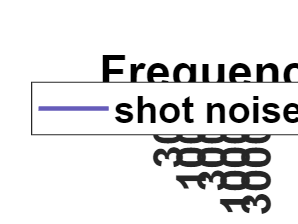


xlim([25 6.5e3]);
ylim([5e-6,6e-4]);
xticks([3e1 1e2 3e2 1e3 3e3]);
xticklabels({'30','100','300','1000','3000'});
yticks([1e-5 3e-5 1e-4 3e-4 1e-3]);
yticklabels({'1e-5','3e-5','1e-4','3e-4','1e-3'});

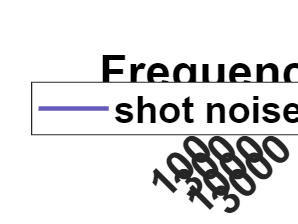


savefig(h1,[main_dir_0,'freq_allan_shot.fig']);
saveas(h1,[main_dir_0,'freq_allan_shot.png']);

### Phase Allan

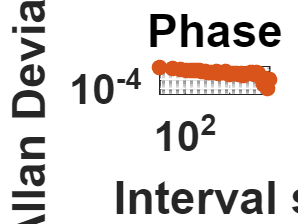


y_lim_low2 = 3e-5;

[tau_k,allan_phase,phase_std] = allan_deviation(phase);

tau = tau_single.*tau_k;

h2 = figure;
I2 = errorbar(tau,allan_phase,phase_std,'.','Color',[0.85 0.33 0.1],...
    'MarkerSize',20,'CapSize',0,'LineWidth',1.8);

%plot(tau,allan_phase,'.','Color',[0.85 0.33 0.1],'MarkerSize',20);

xlim([min(tau) max(tau)]);
ylim([y_lim_low2 max(allan_phase)*1.2]);

xlabel('Interval s');
ylabel('Allan Deviation');
title('Phase','FontName','Arial','FontWeight','bold');

grid on;
set(gca,'FontSize',18,'FontName','Arial','FontWeight','bold',...
    'XScale','log','YScale','log');

set(gcf,'Visible','on');



savefig(h2,[main_dir_0,'phase_allan.fig']);
saveas(h2,[main_dir_0,'phase_allan.png']);


save([main_dir_0,'\allan.mat']);

## Function

function [tau_k,deviation,allan_std] = allan_deviation(phase)

expon = log10(length(phase)/2);
k_list = floor(10.^[0:expon/50:expon]);

for k = 1:length(k_list)

    N = floor(length(phase)/k_list(k));
    var_total = 0;

    for m = 1:N-1
        y_m1 = mean(phase((m-1)*k_list(k)+1:m*k_list(k)));
        y_m2 = mean(phase(m*k_list(k)+1:(m+1)*k_list(k)));
        var1(m) = (y_m2-y_m1).^2;
        var_total = var_total+var1(m);
    end

    tau_k(k) = k_list(k);
    deviation(k) = sqrt(var_total/(N-1)/2);
    allan_std(k) = deviation(k)/sqrt(N);

end
end
